# Conditionals

## [Relational Operators](https://www.mathworks.com/help/matlab/matlab_prog/matlab-operators-and-special-characters.html) and [Logical (Boolean) Operations](https://www.mathworks.com/help/matlab/logical-operations.html)

Before we can write programs that make decisions, we need to understand how MATLAB decides whether something is **true** or **false**.

In MATLAB, a **logical expression** is any statement that compares values or tests conditions. These expressions are evaluated using **relational** and **logical operators**, and the result is either:

- `1` (which means **true**), or

- `0` (which means **false**)

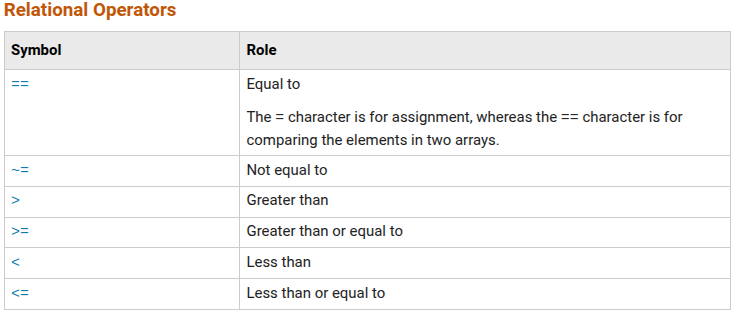

Examples: Single Relations for scalar values 

2 < 8
4 >= 4
3 ~= 5

and variables containing scalars

a = 10;
b = 20;
a < b       
a == b
b == 2*a
a ~= a

Logical operators allow us to **concatenate** or **combine** relational expressions. Just like in regular logic, we can check if **both**, **either**, or **neither** conditions are true.**concatenate** or **combine** relational expressions. 

## 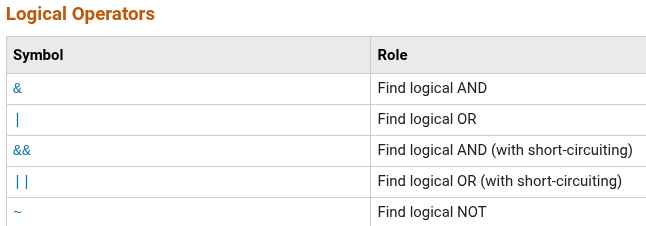

% AND: Both must be true
(5 > 3) && (8 < 10)     

% OR: At least one must be true
(2 > 5) || (7 == 7)     

% NOT: Flip the result
~(4 <= 4)               

**Exercises:**

Replace the `?` with a relational or logical operator (`>`, `<`, `==`, `~=`, `&`, `|`, `~`) so that the expression is **true**.

8 ? 3    

4 ? 4      

(3 < 5) ? (2 > 7)

Explain, in plain language, what the following expression is checking

Predict the results of the following expressions

x = 7;
y = 12;
isRainy = 0;
hasUmbrella = 1;

(x > 5) & (y < 10)

(x < y) | (y == 7)

~(isRainy) | hasUmbrella

(x + y == 19) & ~(x == 7)

## Conditional Flow Control: if - elseif - else - end

## if

Checking if a number is positive

number = 5;

if number > 0
    disp('The number is positive.');
end

Equivalently

if ~(number <= 0)
    disp('The number is positive.');
end

### Combining logical expressions

Boolean logic:

- **AND (**`&&)`is a **short-circuit** operator, meaning it only evaluates the second condition if the first is true. (& is used for element-wise comparisons between arrays.)

- **OR (**`||)` is a **short-circuit** operator that evaluates the second condition only if the first is false. (`|` is an element-wise operator for arrays.)

- **NOT (**`~`**) **negates the condition, returning `true` if the condition is false, and `false` if the condition is true.

- **XOR (**`xor) r`eturns `true` if one of the conditions is true, but not both.

Checking if a number is in a specific range

number = 7;

if ( (number > 0) && (number < 10) )
    disp('The number is between 1 and 9.');
elseif number <= 0 || number >= 10
    disp('The number is either 0 or outside the range 1-9.');
else
    disp('NaN or Inf')
end

## elseif and else

Classify a number

number = -3;

if number > 0
    disp('The number is positive.');
elseif number == 0
    disp('The number is zero.');
else
    disp('The number is negative.');
end

## Flow Control and Conditionals

## continue

Skipping certain iterations of a loop

for i = 1:5
    if mod(i, 2) == 0
        continue; % Skip the rest of the loop for even numbers
    end
    disp(['Number: ', num2str(i)]);
end

If the number is even, `continue` is triggered, which skips to the next iteration of the loop without executing the `disp` statement.

## break

`break` is used to prematurely exit a loop when a certain condition is met.

for i = 1:5
    if i == 3
        disp('Loop stopped at 3');
        break; % Exit the loop when i equals 3
    end
    disp(['Number: ', num2str(i)]);
end

## switch case otherwise

This structure is helpful when you have multiple specific values to check, making it cleaner than using multiple `if-elseif`conditions.

  dayNumber = 3;

switch dayNumber
    case 1
        disp('Monday');
    case 2
        disp('Tuesday');
    case 3
        disp('Wednesday');
    case 4
        disp('Thursday');
    case 5
        disp('Friday');
    otherwise
        disp('Weekend');
end

equivalent to

if dayNumber == 1
    disp('Monday');
elseif dayNumber == 2
    disp('Tuesday');
elseif dayNumber == 3
    disp('Wednesday');
elseif dayNumber == 4
    disp('Thursday');
elseif dayNumber == 5
    disp('Friday');
else
    disp('Weekend');
end
